# outlier fixes - doesn't currently seem to work...



tempkg(1) = hkg2(k);
tempkg(2) = hkg2(k);
outkg2(1) = hkg2(k);

#### trim data

extra step in case of instant clicking regret...

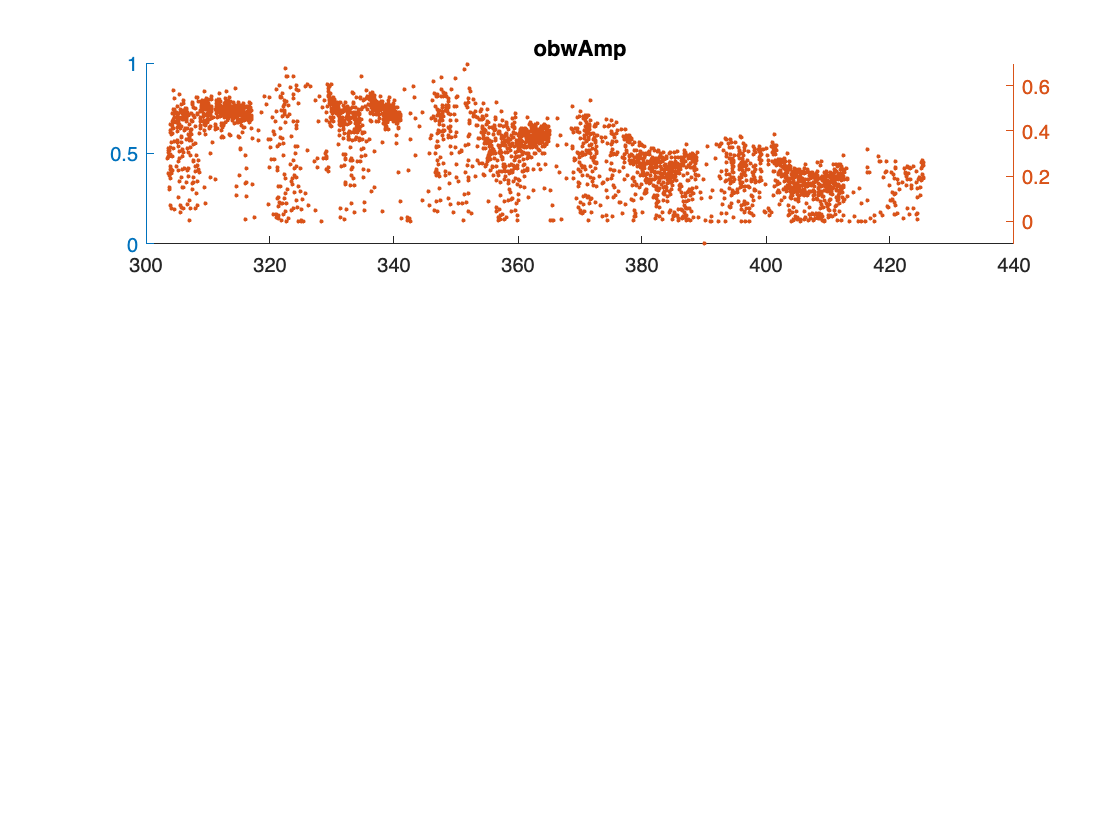

Index exceeds the number of array elements. Index must not exceed 1.

Error in KatieTrimmer (line 11)
    yyaxis right; plot([in(2).s.timcont]/(60*60), [in(2).s.obwAmp], '.');

x = 2;
tempkg(x).e = KatieTrimmer(tempkg(x).e);

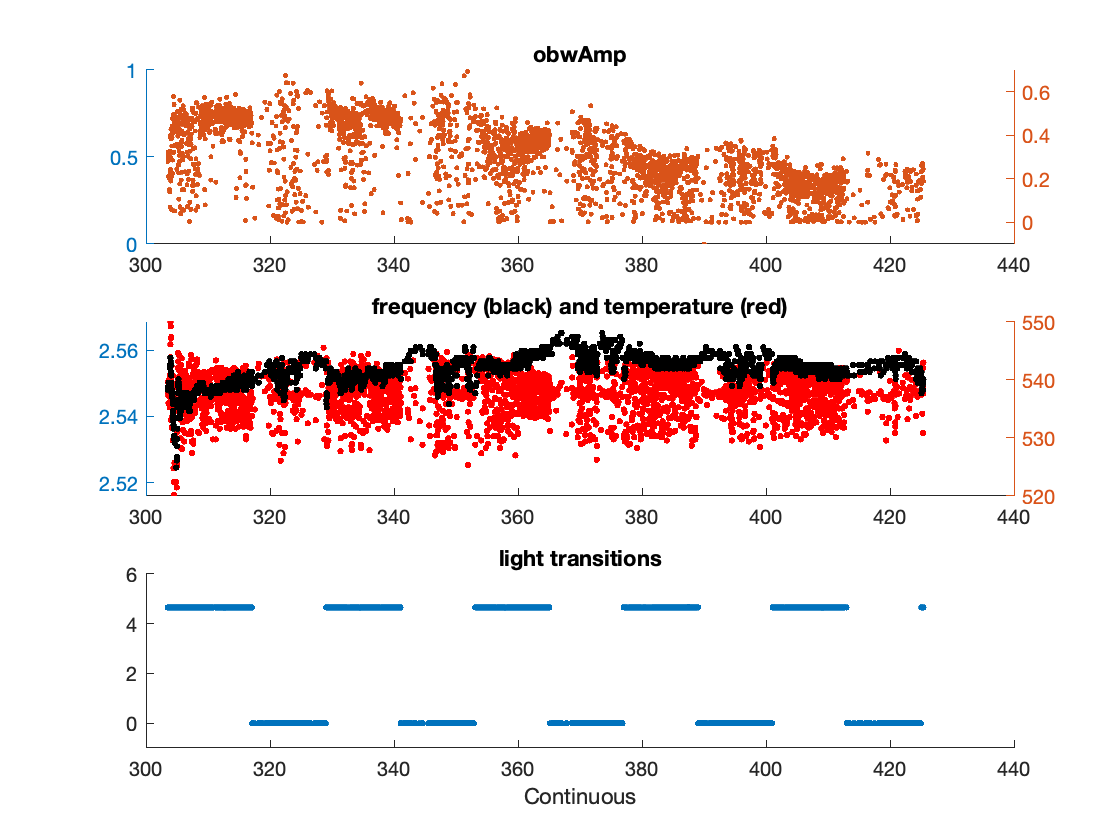

x = 1;
tempkg(x).s  = Katiehkg2Trimmer(tempkg(x).s);

if before was on purpose 

#### Remove outliers

Must be redone after trimming

tempkg(x).idx = KatieRemover(tempkg(x).e);
k_removedsingleplotter(tempkg(x));

channel = 1;
    tempkg(3).e(channel).s.timcont = [tempkg(1).e(channel).s(tempkg(1).idx(channel).obwidx).timcont, tempkg(2).e(channel).s(tempkg(2).idx(channel).obwidx).timcont];
channel = 2;
    tempkg(3).e(channel).s.timcont = [tempkg(1).e(channel).s(tempkg(1).idx(channel).obwidx).timcont, tempkg(2).e(channel).s(tempkg(2).idx(channel).obwidx).timcont];    

xxkg(kk).e = [];
channel = 1;
    %find the times where the hifish and the general data points are the same
     [~, newtimidx, ~] = intersect(int32([xxkg(k).e(channel).s.timcont]), int32([tempkg(3).e(channel).s.timcont]));

for j = 1:length(newtimidx)
xxkg(kk).e(channel).s(j).obwAmp = xxkg(k).e(channel).s(newtimidx(j)).obwAmp;
xxkg(kk).e(channel).s(j).timcont = xxkg(k).e(channel).s(newtimidx(j)).timcont;
xxkg(kk).e(channel).s(j).fftFreq = xxkg(k).e(channel).s(newtimidx(j)).fftFreq;
xxkg(kk).e(channel).s(j).temp = xxkg(k).e(channel).s(newtimidx(j)).temp;
xxkg(kk).e(channel).s(j).light = xxkg(k).e(channel).s(newtimidx(j)).light;
end

channel = 2;
   [~, newtimidx, ~] = intersect(int32([xxkg(k).e(channel).s.timcont]), int32([tempkg(3).e(channel).s.timcont]));


for j = 1:length(newtimidx)
xxkg(kk).e(channel).s(j).obwAmp = xxkg(k).e(channel).s(newtimidx(j)).obwAmp;
xxkg(kk).e(channel).s(j).timcont = xxkg(k).e(channel).s(newtimidx(j)).timcont;
xxkg(kk).e(channel).s(j).fftFreq = xxkg(k).e(channel).s(newtimidx(j)).fftFreq;
xxkg(kk).e(channel).s(j).temp = xxkg(k).e(channel).s(newtimidx(j)).temp;
xxkg(kk).e(channel).s(j).light = xxkg(k).e(channel).s(newtimidx(j)).light;
end

